# Thermoeconomic Analysis Demo

Use ThermoeconomicAnalysis function to compute the exergy cost of a plant

#### Select and check the model file

filename="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\orcvcr\orcvcr_model.json";
data=ReadDataModel(filename);

#### Select the parameters

States=convertCharsToStrings(data.States);
State=convertStringsToChars(States(1));
CostTables=cType.DEFAULT_COST_TABLES;
if data.isResourceCost
    Samples=convertCharsToStrings(data.ResourceSamples);
    ResourceSample=convertStringsToChars(Samples(1));
    CostTables='ALL';
end

#### Perform Cost Analysis

res=ThermoeconomicAnalysis(data,'State',State, ...
    'CostTables',CostTables,'ResourceSample',ResourceSample,'Show',true);

Process Exergy Cost

Key        P*(kW)    Pe*(kW)    Pr*(kW)     F*(kW)     R*(kW)
——————————————————————————————————————————————————————————————
BLR         561.9      462.1       99.8      462.1       99.8
TRB         559.6      436.8      122.8      534.3       25.3
PMP          36.2       26.9        9.3       34.7        1.6
CMP         635.7      409.9      225.8      525.1      110.6
EVAP        462.1      298.0      164.1      462.1        0.0
GEN          34.7       26.9        7.8       34.5        0.2
VEXP         91.8       59.2       32.6       91.8        0.0
CND         145.6      104.9       40.7      145.6        0.0


Process Unit Exergy Cost

Key      kP*(J/J)  kPe*(J/J)  kPr*(J/J)   kF*(J/J)   kR*(J/J)     k(J/J)
—————————————————————————————————————————————————————————————————————————
BLR        1.7210     1.4153     0.3057     1.0000     0.3057     1.4153
TRB        2.2831     1.7822     0.5009     1.7634     0.1032     1.2362
PMP        2.8536     2.1190     0.73

#### Show the default thermoeconomic analysis graph

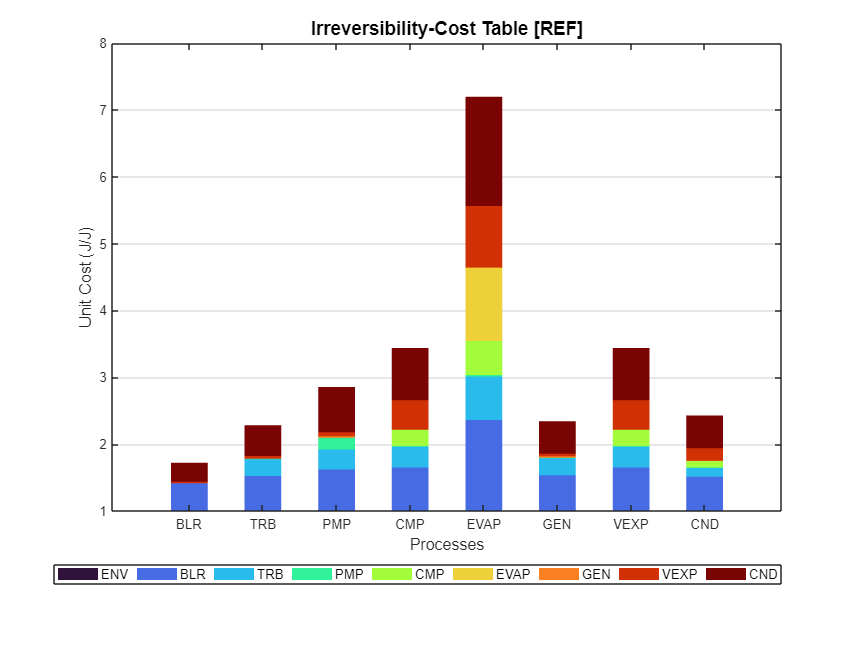

ShowGraph(res);